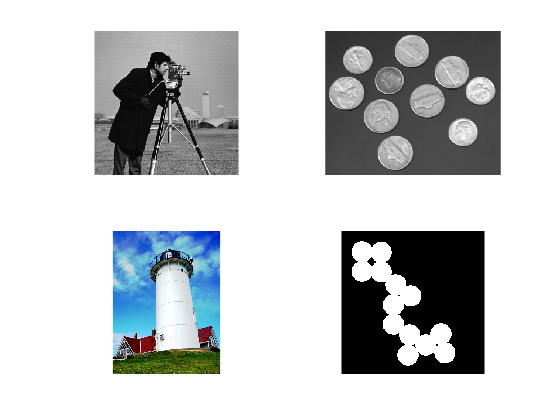

CameraManGreyScale = imread('cameraman.tif');
Coins = imread('coins.png');
Circles = imread('circles.png');
Lighthouse = imread('lighthouse.png');
figure % new figure - note not followed by semi-colon
subplot(2, 2, 1); % define 2 by 2 space and specify 1st quadrant
imshow(CameraManGreyScale);
subplot(2, 2, 2); % on 2 by 2 space specify 2nd quadrant
imshow(Coins);
subplot(2, 2, 3); % on 2 by 2 space specify 3rd quadrant
imshow(Lighthouse);
subplot(2,2,4);
imshow(Circles);


%%% Multiple value return
[imgHeight, imgWidth] = size(Coins);
disp(imgHeight);

   246



disp(imgWidth);

   300



## Obtain data from imhist

[CoinCounts, coinBinLocations ] = imhist(Coins, 128);
disp("Hist Count for Coins: " + CoinCounts);

    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 0"
    "Hist Count for Coins: 1"
    "Hist Count for Coins: 10"
    "Hist Count for Coins: 11"
    "Hist Count for Coins: 30"
    "Hist Count for Coins: 30"
    "Hist Count for Coins: 29"
    "Hist Count for Coins: 34"
    "Hist Count for Coins: 36"
    "Hist Count for Coins: 38"
    "Hist Count for Coins: 38"
    "Hist Count for Coins: 45"
    "Hist Count for Coins: 45"
    "Hist Count for Coins: 73"
    "Hist Count for Coins: 341"
    "Hist Count for Coins: 1109"
    "Hist Count for Coins: 1483"
    "Hist Count for Coins: 1574"
    "Hist Count for Coins: 2275"
    "Hist Count for Coins: 3279"
    "Hist Count for Coins: 3480"
    "Hist Count for Coins: 3113"
    "

disp("Bin Locations for Coins" + coinBinLocations);

    "Bin Locations for Coins0"
    "Bin Locations for Coins2.007874"
    "Bin Locations for Coins4.015748"
    "Bin Locations for Coins6.023622"
    "Bin Locations for Coins8.031496"
    "Bin Locations for Coins10.03937"
    "Bin Locations for Coins12.04724"
    "Bin Locations for Coins14.05512"
    "Bin Locations for Coins16.06299"
    "Bin Locations for Coins18.07087"
    "Bin Locations for Coins20.07874"
    "Bin Locations for Coins22.08661"
    "Bin Locations for Coins24.09449"
    "Bin Locations for Coins26.10236"
    "Bin Locations for Coins28.11024"
    "Bin Locations for Coins30.11811"
    "Bin Locations for Coins32.12598"
    "Bin Locations for Coins34.13386"
    "Bin Locations for Coins36.14173"
    "Bin Locations for Coins38.14961"
    "Bin Locations for Coins40.15748"
    "Bin Locations for Coins42.16535"
    "Bin Locations for Coins44.17323"
    "Bin Locations for Coins46.1811"
    "Bin Locations for Coins48.18898"
    "Bin Locations for Coins50.19685"
    "Bin Locations f

## Display a histogram

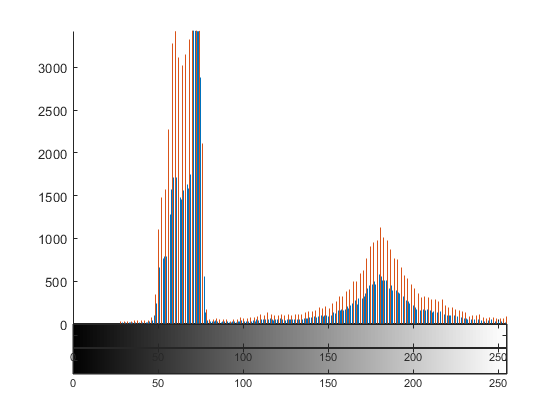

figure;
hold on;
imhist(Coins); % Display histogram of your coins image.
imhist(Coins, 128); % Display histogram with 128 bins.
hold off;

## Img Resize

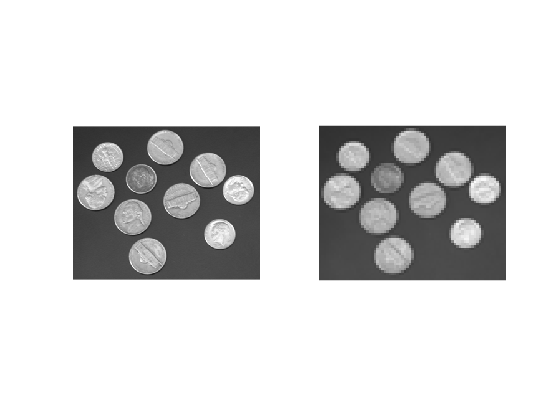

smallCoins = imresize(Coins, 0.25);
figure
subplot(1,2,1);
imshow(Coins);
subplot(1,2,2);
imshow(smallCoins);

## Making Small Coins Big Again

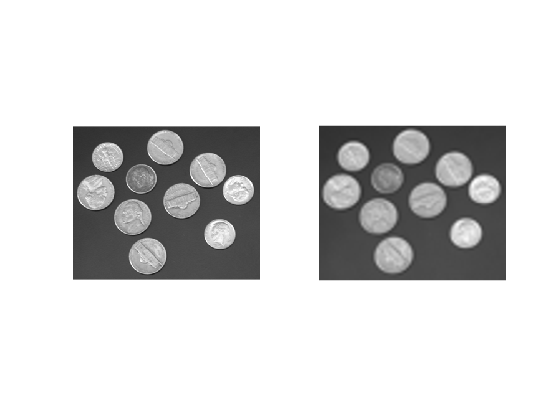

largeCoins = imresize(smallCoins, 5);
figure
subplot(1,2,1);
imshow(Coins);
subplot(1,2,2);
imshow(largeCoins);

## Image Resize with bilinear and nearest interpolation

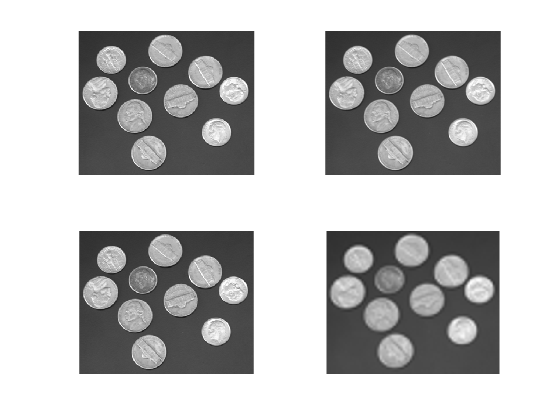

largeBilinear = imresize(Coins, 3, "Bilinear");
largeNearest = imresize(Coins,3,"Nearest");
figure
subplot(2,2,1);
imshow(Coins);
subplot(2,2,2);
imshow(largeBilinear);
subplot(2,2,3);
imshow(largeNearest);
subplot(2,2,4);
imshow(largeCoins);

## Histogram Equalisation

coinsEq = histeq(Coins);
figure Name Histogram-Equalisation
subplot(1,2,1);
disp("Original");

Original


imshow(Coins);
subplot(1,2,2);
disp("Equalised");

Equalised


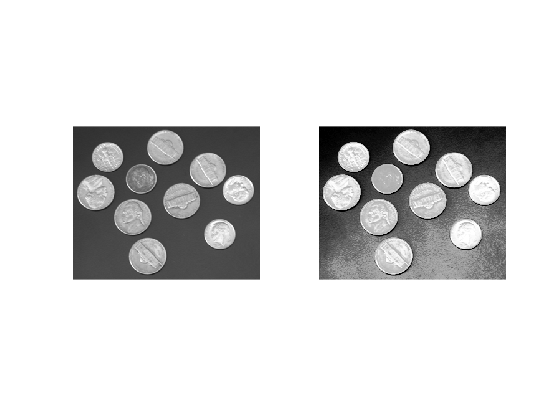

imshow(coinsEq);

## Colour Channels

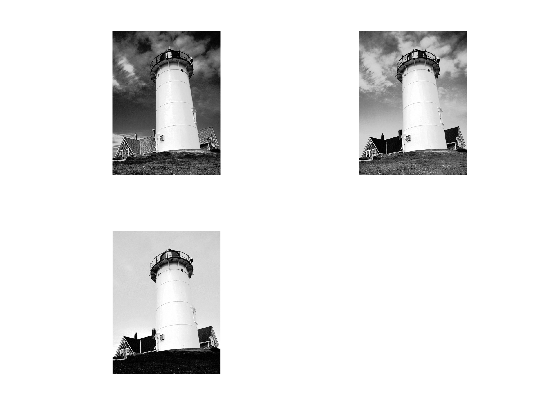

redChannel = Lighthouse(:, :, 1);
greenChannel = Lighthouse(:, :, 2);
blueChannel = Lighthouse(:, :, 3);
figure
subplot(2,2,1);
imshow(redChannel);
subplot(2,2,2);
imshow(greenChannel);
subplot(2,2,3);
imshow(blueChannel);

## Convert to HSV

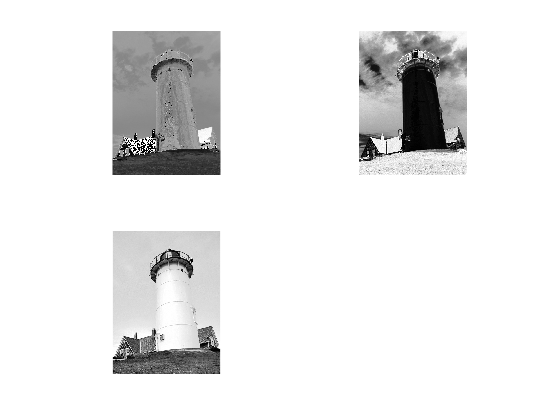

HSV_lighthouse = rgb2hsv(Lighthouse);
hueChannel = HSV_lighthouse(:,:,1);
satChannel = HSV_lighthouse(:,:,2);
valChannel = HSV_lighthouse(:,:,3);
figure
subplot(2,2,1);
imshow(hueChannel);
subplot(2,2,2);
imshow(satChannel);
subplot(2,2,3);
imshow(valChannel);

## Convert to rgb2ycbcr

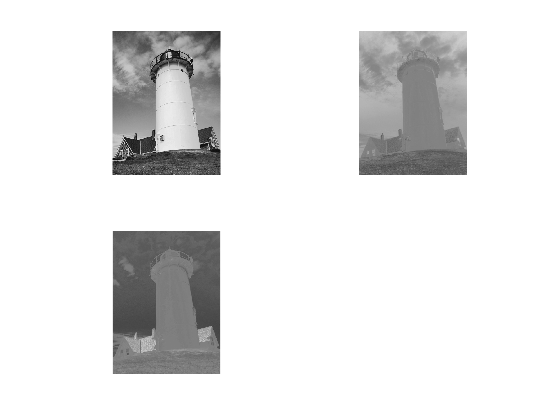

YCBCR_Lighthouse = rgb2ycbcr(Lighthouse);
luma = YCBCR_Lighthouse(:,:,1);
BlueDifference = YCBCR_Lighthouse(:,:,2);
RedDifference = YCBCR_Lighthouse(:,:,3);
figure
subplot(2,2,1);
imshow(luma);
subplot(2,2,2);
imshow(BlueDifference);
subplot(2,2,3);
imshow(RedDifference);

## Convert to L*a*b* colour space

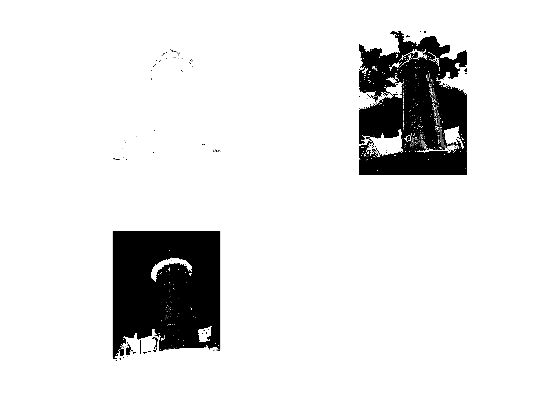

LabLightHouse = rgb2lab(Lighthouse);
b2w = LabLightHouse(:,:,1);
g2r = LabLightHouse(:,:,2);
b2y = LabLightHouse(:,:,3);
figure
subplot(2,2,1);
imshow(b2w);
subplot(2,2,2);
imshow(g2r);
subplot(2,2,3);
imshow(b2y);